## Schrittmotor Inbetriebnahme

clc; clear;

### **Schrittmotor Parameter**

N = 12800;          % Schritte pro volle Umdrehung
dphi = 360/N;   % [°/Schritt]

#### Trace Daten auslesen aus .csv Datei

M = readmatrix('table_trace.csv', 'NumHeaderLines',2);
M = M(isfinite(M(:,1)),:);
t = M(:,1);
Y = M(:,2);
n = length(t);

### Gesamtimpulse zählen

imp_index = find(M(:,2)==1);
pulses = length(imp_index);

imp_duration = t(imp_index+1, 1) - t(imp_index,1);
min_imp = min(imp_duration);
max_imp = max(imp_duration);
mean_imp = mean(imp_duration);

fprintf("Durchschnittliche Impulsdauer: %.4f us.", mean_imp*1000*1000);

Durchschnittliche Impulsdauer: 2.2192 us.

fprintf("Min. Impulsdauer: %.4f us.", min_imp*1000*1000);

Min. Impulsdauer: 2.1660 us.

fprintf("Max. Impulsdauer: %.4f us.", max_imp*1000*1000);

Max. Impulsdauer: 2.2500 us.

fprintf("Anzahl der Impulse: %d", pulses);

Anzahl der Impulse: 12800

### Streckenprofil

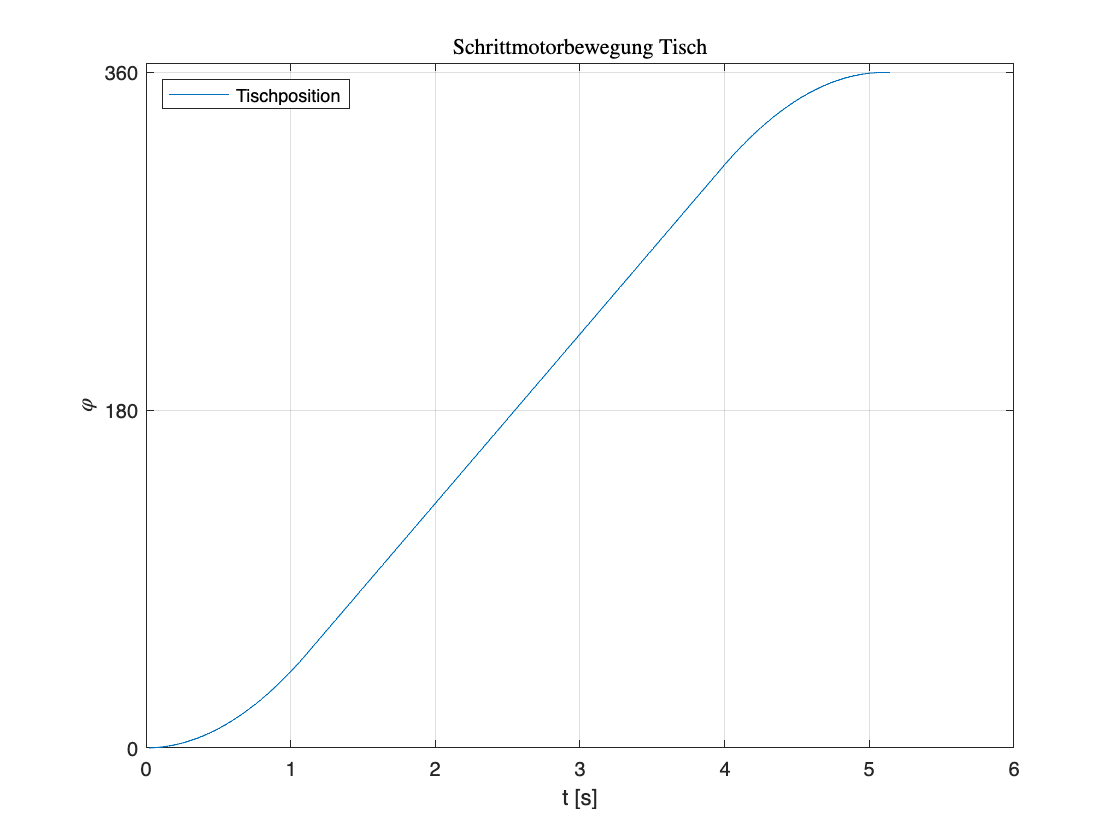

phi     = zeros(1, length(imp_index));
t_phi   = zeros([1, length(imp_index)]);

x = 1;
for i = imp_index'
    if i == 1
        phi(1) = dphi;
    else
        phi(x) = phi(x-1) + dphi;
    end
    t_phi(x)    = t(i);
    x = x + 1;
end

plot(t_phi,phi);
title("Schrittmotorbewegung Tisch",'Interpreter','Latex')
xlabel("t [s]")
ylabel("$\varphi$", 'Interpreter','Latex')
grid("on");
legend('Tisch Position', Location='northwest')
ylim([0, 365.0]);
yticks([0, 180, 360])